clc
clear

imgPath = 'landscape.jpg'

imgPath = 'landscape.jpg'

## Image preprocessing

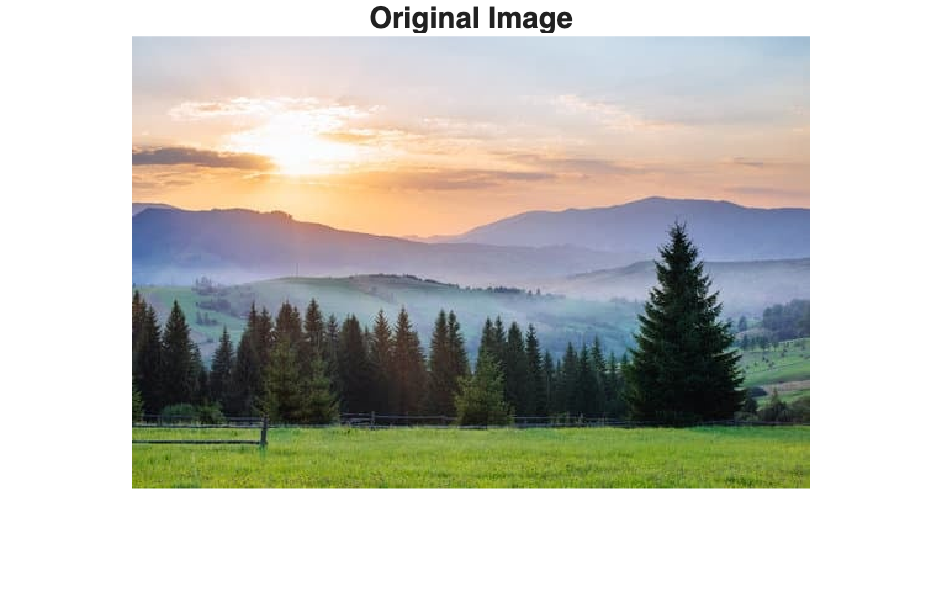

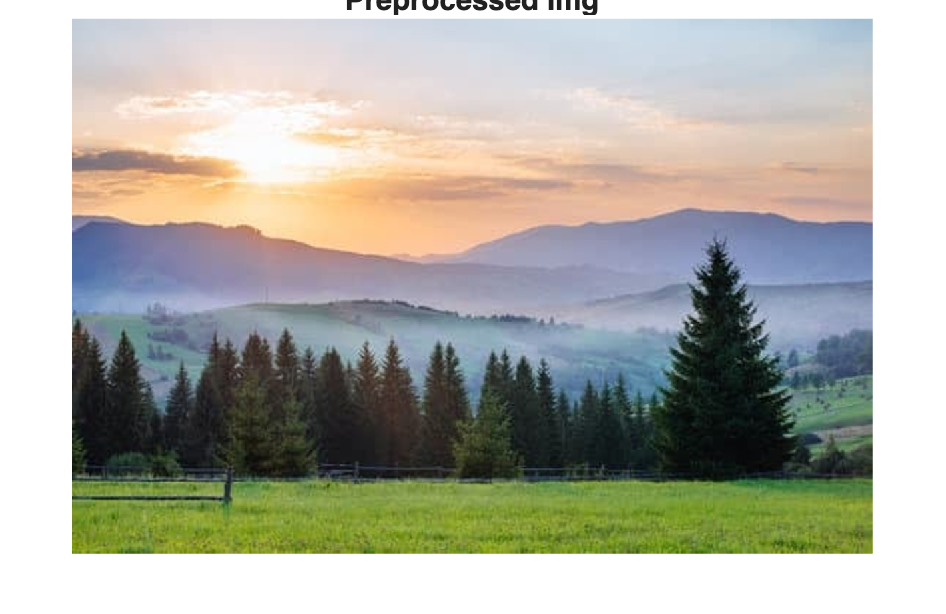

minW = 600;        % Min input width (px)
maxW = 3000;       % Max input width (px)
Wout = 1200;       % Output width (px)

img = im2double(imread(imgPath));
processedImg = preprocessImage(img, minW, maxW, Wout);

Ilab = rgb2lab(processedImg);


## Color palette generation & palette optimization

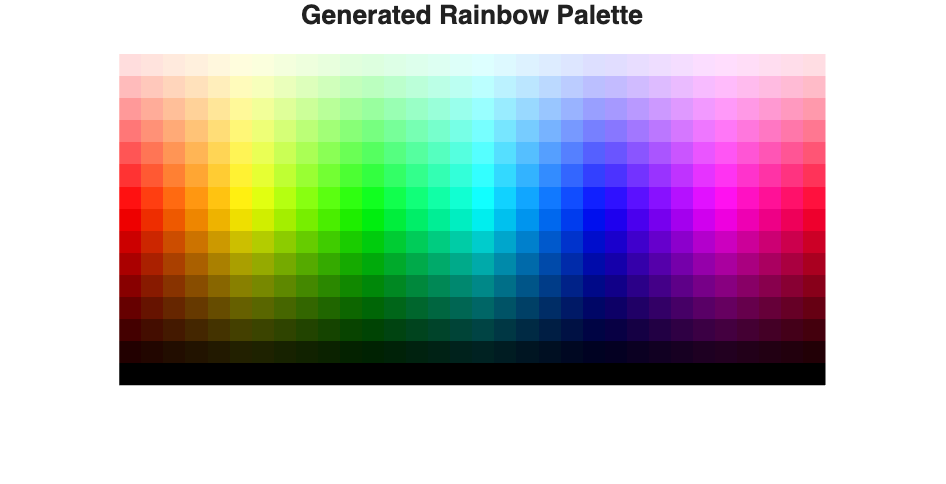

numColors= 32;      % Number of base colors
numShades = 16;     % Number of shades of the base colors
[paletteLab, paletteImage] = make_rainbow_palette(numColors, numShades);

figure;
imshow(imresize(paletteImage, 20, 'nearest')); 
title('Generated Rainbow Palette');


% TODO: Optimize the color palette after the image
% TODO: Print and show the optimized palette


## Image reconstruction

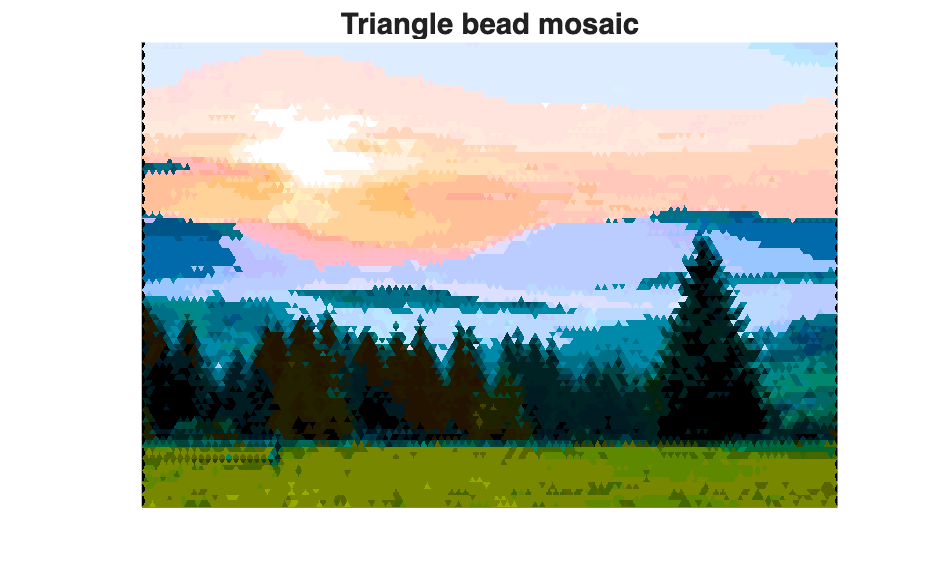

side = 12;         % Triangle/Bead size (px)

% TODO: Reconstruct using the optimized palette
[mosaicRGB, idxMap] = render_triangle_mosaic(Ilab, paletteLab, side);

figure;
image(mosaicRGB);
axis image off;
title('Triangle bead mosaic');